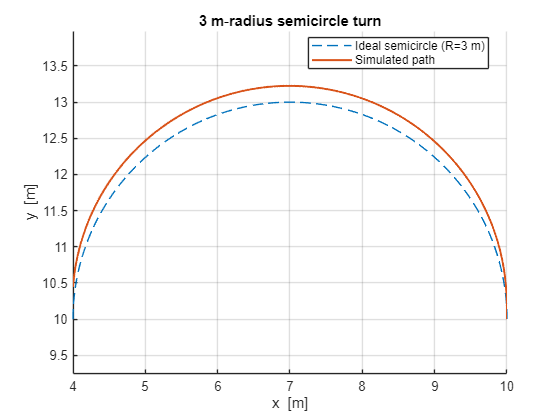



% function q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v)
% 
% global dt; global DT;

% model of a vehicle with closed-loop steering and velocity control

% the combined effect of steering/vehicle inertia and control is

% a first order system for steering (tau_gamma) and velocity (tau_v)

% state is vector q

% q(1) -> x

% q(2) -> y

% q(3) -> theta (orientation in world frame)

% q(4) -> gamma (steering angle)

% q(5) -> v (linear velocity)

% inputs are:

% u(1) -> desired steering angle (gamma_d)

% u(2) -> desired linear velocity (v_d)

%%
function q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v)
    global dt; 
    global DT;

    % Extract current state
    x     = q(1);
    y     = q(2);
    theta = q(3);
    gamma = q(4);
    v     = q(5);

    % Desired inputs
    gamma_d = u(1);  % desired steering angle
    v_d     = u(2);  % desired velocity

    % Saturate desired inputs
    gamma_d = max(min(gamma_d, umax(1)), umin(1));
    v_d     = max(min(v_d, umax(2)), umin(2));

    % First-order dynamics for steering and velocity
    dgamma = (gamma_d - gamma) / tau_gamma;
    dv     = (v_d - v) / tau_v;

    % Euler integration to update gamma and v
    gamma = gamma + dt * dgamma;
    v     = v + dt * dv;

    % Bicycle model kinematics
    dx     = v * cos(theta);
    dy     = v * sin(theta);
    dtheta = v * tan(gamma) / L;

    % Euler integration to update pose
    x     = x + dt * dx;
    y     = y + dt * dy;
    theta = theta + dt * dtheta;

    % Saturate state vector
    x     = max(min(x, Qmax(1)), Qmin(1));
    y     = max(min(y, Qmax(2)), Qmin(2));
    theta = max(min(theta, Qmax(3)), Qmin(3));
    gamma = max(min(gamma, Qmax(4)), Qmin(4));
    v     = max(min(v, Qmax(5)), Qmin(5));

    % Pack next state
    q_next = [x; y; theta; gamma; v];
end

%Parameters
L          = 2.5;                 % wheel‑base         [m]
gamma_max  = pi/4;                % |γ_max|            [rad]  (≈ 45°)
v_max      = 5;                   % |v_max|            [m s⁻¹]
dt         = 0.01;                % integration step   [s]
DT         = 0.10;                % (unused here, keep for completeness)
vd         = 1.0;                 % commanded speed    [m s⁻¹]

% Workspace access for the dynamics function
global dt  DT

% Steering needed for R = 3 m  ➜  γ_d = arctan(L / R)
R          = 3.0;                                % requested radius [m]
gamma_cmd  = atan(L/R);
assert(gamma_cmd <= gamma_max, 'γ_d exceeds γ_max!')

% Simulation horizon: half‑circumference  s = πR  so  T = s / v
T          = pi*R / vd;
Nsteps     = ceil(T/dt);

% State limits (set very large so they never clip)
Qmin  = [-Inf -Inf -Inf  -gamma_max      0];
Qmax  = [ Inf  Inf  Inf   gamma_max   v_max];
umin  = [-gamma_max  -v_max];
umax  = [ gamma_max   v_max];

% Initial state: rear‑axle at (10,10), heading +y  (θ = π/2)
q      = [10; 10; pi/2; 0; vd];                  % [x y θ γ v]

% Storage for trace
trail  = zeros(Nsteps+1,2);
trail(1,:) = q(1:2).';

% Main simulation loop
for k = 1:Nsteps
    u        = [gamma_cmd; vd];                 % constant inputs
    q        = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, 0.2, 0.5);     % τ_γ=0.2 s, τ_v=0.5 s
    trail(k+1,:) = q(1:2).';
end

% Plot ideal semicircle and the driven path
figure, hold on, axis equal, grid on
xlabel('x  [m]'), ylabel('y  [m]'), title('3 m‑radius semicircle turn')

% Ideal semicircle (left‑hand turn, centre at (7,10))
phi  = linspace(0,pi,181);                      % 0 -> 180°
xc   = 10 - R;  yc = 10;                        % centre coords
plot(xc + R*cos(phi), yc + R*sin(phi), '--');   % ideal path

% Simulated trace
plot(trail(:,1), trail(:,2), 'LineWidth',1.5);

legend('Ideal semicircle (R=3 m)', 'Simulated path','Location','best')